# 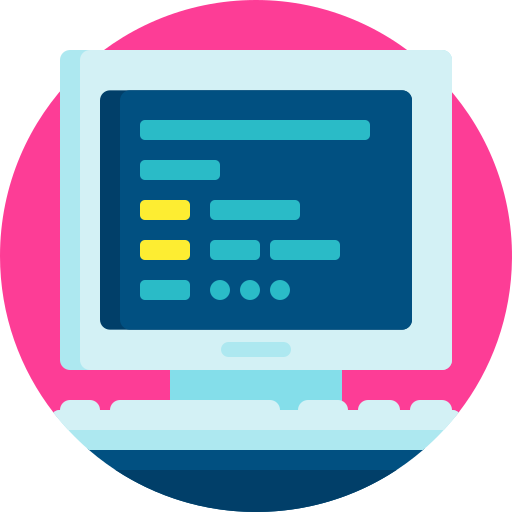

# Virtual Lab 1 - Reference Frames and Vector Mappings

#### This Virtual Lab covers Chapter 2 of the course notes

- This Virtual Lab will require both pen-on-paper work, as well as the use of MATLAB coding. The intention is to be able to solve the problems on paper (as you would in a Test/Exam) and then ratify the result using MATLAB.

- Make sure to save this file somewhere where you can access it again later, e.g. Google Drive/OneDrive/MATLAB Drive/USB. 

- This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output Inline`.

- Each Section of this Live Script must be run individually. You can run Sections by using the `Run Section` button under the `LIVE EDITOR` ribbon (at the top of the screen), or using CNTL+ENTER (or CMD+ENTER).

## Rotation matrices

Rotation matrices are used to *encode* the orientation of one reference frame with respect to another. Given two reference frames of interest, frame$\{B\}$ and frame$\{W\}$, which we refer to as our body-frame and inertial-frame, respectively, we can construct a rotation matrix, ${^W {\bf R}_B}$, that describes the orientation of frame$\{B\}$ with respect to frame $\{W\}$. 

There are different approaches to constructing ${^W {\bf R}_B}$, but the "first principles" approach is to individiually project each principle axis in frame$\{B\}$ onto each axis in frame$\{W\}$. 

### Defining reference frames

The principal axes in frame $\{W\}$ are always by definition

,

,

.

For the *particular* configuration under consideration for this Virtual Lab, the principal axes of $\{B\}$ with respect to $\{W\}$ are given as

,

,

.

We can plot our world-frame to see if our understanding matches the geometric representation. MATLAB's [`plotTransforms`](https://www.mathworks.com/help/nav/ref/plottransforms.html) function requires a postion vector and quaternion to plot a 3D cartesian coordinate system. We will not have covered quaternions yet in Week 1, but we can convert rotation matrices to quaternions using MATLAB's [`rotm2quat`](https://www.mathworks.com/help/nav/ref/rotm2quat.html) function, e.g.

R = eye(3,3)    %identity matrix
q = rotm2quat(R) %identity (or null) quaternion

Note that a rotation matrix of ${{\bf R}}={\bf I}$ implies that there is no rotation (a null rotation). This is the same as saying that each respective principle axis in frame$\{B\}$ is parallel to the corresponding axis in frame $\{W\}$(the two frames lie on top of each other exactly). We will start by plotting our world-frame axes, which will be centred at $[0~0~0]^T$:

figure
c = [0 0 0];% location of frame {W} origin wrt frame {W}.
plotTransforms(c,q,"FrameAxisLabels","on","FrameLabel","W");
axis equal
grid on
title('frame $\{W\}$','Interpreter','latex')

If all is correct, you should see a reference frame that is centred on the origin, with the $\hat{\bf x}_W$-axis shown in red, $\hat{\bf y}_W$-axis shown in green, and $\hat{\bf z}_W$-axis shown in blue. Ensure that the axis direction make sense to you before continuing, and that *right-hand rule* is obeyed.

**Note: **if you click on the resulting figure, some figure controls will appear (as shown below). The second icon, for example, will allow you to rotate the figure, which may be helpful going forward.

**  Question 1: **Find the $3\times 3$ rotation matrix that describes the orientation of  $\{B\}$ with respect to $\{W\}$?

%Code block if required


We can also display $\{B\}$with respect to frame $\{W\}$ using `R_b2w`. You can assume that the origin is also located at $[0~0~0]^T$ for now.

figure
plotTransforms([0 0 0],rotm2quat(R_b2w),"FrameAxisLabels","on","FrameLabel","B");
axis equal
grid on
title('frame $\{B\}$ wrt frame $\{W\}$','Interpreter','latex')

Remember to use the 3D rotate tool on the figure! 

Because ${^W {\bf R}_B} \neq {\bf I}$, the two reference frames will not be coincident. What you should notice is that frame$\{B\}$ has been rotated about a single principle axis in frame $\{W\}$. That is, the difference between the two frames is a single rotation about a defined vector. 

We can also plot the two frames side by side using.

figure,
subplot(1,2,1)
plotTransforms(c,q,"FrameAxisLabels","on","FrameLabel","W");
axis equal,grid on;
title('frame $\{W\}$ wrt frame $\{W\}$','Interpreter','latex')
subplot(1,2,2)
plotTransforms(c,rotm2quat(R_b2w),"FrameAxisLabels","on","FrameLabel","B");
axis equal,grid on;
title('frame $\{B\}$ wrt frame $\{W\}$','Interpreter','latex')

**  Question 2:** Which vector has frame$\{B\}$ been rotated about to obtain its current orientation?

%Code block if required


**  Question 3:** What is the corresponding rotation angle (in radians)?

%Code block if required


We will learn later on that both exponential coordinates and quaternions encode this type of rotation, which relies on a rotation vector and rotation angle (see **Chapter 3** for a sneak peak). We can plot the rotation vector using the function [`line`](https://www.mathworks.com/help/matlab/ref/line.html)

figure,
subplot(1,2,1)
plotTransforms(c,q,"FrameAxisLabels","on","FrameLabel","W");
vec = line([0 v(1)],[0 v(2)],[0 v(3)]); %define vector. Use "help line" in Command Window for more information
vec.Color = 'black';    
vec.Marker = 'x';   
vec.LineWidth = 2;  
vec.LineStyle = '--';
axis equal,grid on;
title('frame $\{W\}$ wrt frame $\{W\}$','Interpreter','latex')

subplot(1,2,2)
plotTransforms(c,rotm2quat(R_b2w),"FrameAxisLabels","on","FrameLabel","B");
vec = line([0 v(1)],[0 v(2)],[0 v(3)]);
vec.Color = 'black';
vec.Marker = 'x';
vec.LineWidth = 2;
vec.LineStyle = '--';
axis equal,grid on;
title('frame $\{B\}$ wrt frame $\{W\}$','Interpreter','latex')

Ensure that your vector is pointing in the right direction according to *right-hand rule* and try imagine the reference frames rotating about the vector.

### Rotating vectors

Given our rotation matrix from before (use this to check your previous answer!) of 

${^W{\bf R}_B=\pmatrix{1 & 0 & 0 \cr 0 & 0 & -1 \cr 0 & 1 &0}$ , 

R_b2w = [1 0 0;
         0 0 -1;
         0 1 0];    %rotation matrix that encodes orientation of frame {B} wrt frame {W}

we can rotate (or map) vectors from one reference frame to another using ${^W{\bf R}_B}$, but only if the two reference frame origins are coincident. For example, if we wanted to represent the vector ${^B{\bf p}=[1~0~0]^T$ in the world frame, we would use 


$${^W{\bf p}={^W{\bf R}_B}{^B{\bf p}.$$


p_b = [1 0 0]'; %position of point p, described relative to frame {B}
p_w = R_b2w*p_b    %position of point p, described relative to frame {W}

We can then plot the vector in the two frames to make sense of its geometric meaning.

%Code to plot body-frame axes and p_b
figure
subplot(1,2,1),hold on
plotTransforms([0 0 0],[1 0 0 0],"FrameAxisLabels","on","FrameLabel","B");   
vec = line([0 p_b(1)],[0 p_b(2)],[0 p_b(3)]);
vec.Color = 'black';
vec.Marker = 'x';
vec.LineWidth = 2;
vec.LineStyle = '--';
axis equal, grid on
title('Body frame')

%Code to plot inertial-frame axes and p_w = R.p_b
subplot(1,2,2),hold on
plotTransforms([0 0 0],[1 0 0 0],"FrameAxisLabels","on","FrameLabel","W");   
vec = line([0 p_w(1)],[0 p_w(2)],[0 p_w(3)]);
vec.Color = 'black';
vec.Marker = 'x';
vec.LineWidth = 2;
vec.LineStyle = '--';
axis equal, grid on
title('World frame')

It is possibly of no surprise to you that the vector ${^B{\bf p}}=[1~0~0]^T$is identical in both reference frames (for this particular rotation matrix!). This is because the first column of ${^W{\bf R}_B}$ is equal to $[1~0~0]^T$. In other words, ${^W \hat{\bf x}_B}=\hat{\bf x}_B={^B{\bf p}}$ (the $x$-axis of both reference frames are parallel). Take a look at how ${^B{\bf p}}$ multiplies into ${^W{\bf R}_B}$ to see why this happened mathematically. This result wont be the case in general for any arbitrary vector.

**  Question 4: **Assuming the origins of {B} and {W} are coincident, what is the world-frame representation of the following vectors when ${^W{\bf R}_B=\pmatrix{1 & 0 & 0 \cr 0 & 0 & -1 \cr 0 & 1 &0}$ .

- 
$${^B{\bf p}=[0~1~0]^T$$


- 
$${^B{\bf p}=[0~0~1]^T$$


- 
$${^B{\bf p}=[1~1~0]^T$$


Calculate the answers by hand using ${^W{\bf p}={^W{\bf R}_B}{^B{\bf p}$, and then verify your solution using the code below.

p_bx = 0;
p_by = 0;
p_bz = 1;
p_b = [p_bx p_by p_bz]';
R_b2w = [1 0 0;
         0 0 -1;
         0 1 0];
p_w = R_b2w*p_b;

figure
subplot(1,2,1)
plotTransforms([0 0 0],[1 0 0 0],"FrameAxisLabels","on","FrameLabel","B"),hold on
vec = line([0 p_b(1)],[0 p_b(2)],[0 p_b(3)]);
vec.Color = 'black';
vec.LineStyle = '--';
vec.Marker = 'x';
vec.LineWidth = 2;
axis equal, grid on
title('Bodyframe')

subplot(1,2,2)
plotTransforms([0 0 0],[1 0 0 0],"FrameAxisLabels","on","FrameLabel","W"),hold on
vec = line([0 p_w(1)],[0 p_w(2)],[0 p_w(3)]);
vec.Color = 'black';
vec.LineStyle = '--';
vec.Marker = 'x';
vec.LineWidth = 2;
axis equal, grid on
title('World frame') 

We can also rotate vectors from the world frame to the body frame by inverting ${^W{\bf R}_B}$, namely ${^W{\bf R}_B^{-1}}={^W{\bf R}_B^{T}}={^B{\bf R}_W}$. 

The code block below allows you to specify ${^W{\bf p}}$ and then determine $^B{\bf p}$.

p_wx = 1;
p_wy = 1;
p_wz = 0;
p_w = [p_wx p_wy p_wz]';
R_b2w = [1 0 0;
         0 0 -1;
         0 1 0];
p_b = (R_b2w)'*p_w;

figure
subplot(1,2,1)
plotTransforms([0 0 0],[1 0 0 0],"FrameAxisLabels","on","FrameLabel","B"),hold on
vec = line([0 p_b(1)],[0 p_b(2)],[0 p_b(3)]);
vec.Color = 'black';
vec.LineStyle = '--';
vec.Marker = 'x';
vec.LineWidth = 2;
axis equal, grid on
title('Body frame')

subplot(1,2,2)
plotTransforms([0 0 0],[1 0 0 0],"FrameAxisLabels","on","FrameLabel","W"),hold on
vec = line([0 p_w(1)],[0 p_w(2)],[0 p_w(3)]);
vec.Color = 'black';
vec.LineStyle = '--';
vec.Marker = 'x';
vec.LineWidth = 2;
axis equal, grid on
title('World frame')

 What you should see is that the concept of rotating vectors in either direction is conceptually the same, we just need to use the correct mapping (rotation matrix in this case). 

## Generalised vector mappings

Rotation matrices can correctly map vectors between reference frames when the origins are coincident, but in the general case, there will be an offset between the two frame origins of ${^W{\bf t}_B$ (when described in the world frame). The generalised equation to describe vector mappings from$\{B\}$ to $\{W\}$is 

${^W{\bf p}}={^W{\bf R}_B}{^B{\bf p}}+{^W{\bf t}_B}$.

Note the addition of ${^W{\bf t}_B}$, which captures the displacement between the two reference frame origins. Continuing with our rotation matrix from before of 

${^W{\bf R}_B=\pmatrix{1 & 0 & 0 \cr 0 & 0 & -1 \cr 0 & 1 &0}$ , 

we can see how changing ${^W{\bf t}_B$ will affect the location of $\{B\}$ with respect to $\{W\}$.

tb2w_x = 5;
tb2w_y = 0;
tb2w_z = 0;
tb2w = [tb2w_x tb2w_y tb2w_z];

figure,hold on
plotTransforms([0 0 0],[1 0 0 0])
plotTransforms(tb2w,rotm2quat(R_b2w))
axis equal
grid on

We will now assume that ${^W{\bf t}_B=[3~3~0]^T$.

tb2w = [3 3 0];

Using the code below, we can see how vectors specified in the body frame will also be posed in the world frame.

p_bx = 0;
p_by = 0;
p_bz = 0;
p_b = [p_bx p_by p_bz]';
R_b2w = [1 0 0;
         0 0 -1;
         0 1 0];
p_w = R_b2w*p_b+tb2w'

figure,hold on
plotTransforms(tb2w,rotm2quat(R_b2w),"FrameAxisLabels","on","FrameLabel","B");   
vec = line([tb2w(1) p_w(1)],[tb2w(2) p_w(2)],[tb2w(3) p_w(3)]);
vec.Color = 'magenta';
vec.LineStyle = '--';
vec.Marker = 'x';
vec.LineWidth = 2;

plotTransforms([0 0 0],[1 0 0 0],"FrameAxisLabels","on","FrameLabel","W");   
vec = line([0 p_w(1)],[0 p_w(2)],[0 p_w(3)]);
vec.Color = 'black';
vec.LineStyle = '--';
vec.Marker = 'x';
vec.LineWidth = 2;
axis equal, grid on

The magenta vector describes vector ${^B{\bf p}}$, whereas black vector describes vector ${^W{\bf p}}={^W{\bf R}_B}{^B{\bf p}}+{^W{\bf t}_B}$.

**  Question 5: **Using the setup as above, with ${^W{\bf R}_B=\pmatrix{1 & 0 & 0 \cr 0 & 0 & -1 \cr 0 & 1 &0}$ and ${^W{\bf t}_B=[3~3~0]^T$, what is the world-frame representation of the following vectors:

- ${^B{\bf p}=[0~1~0]^T$?

- ${^B{\bf p}=[0~0~1]^T$?

- ${^B{\bf p}=[1~1~0]^T$?

First calculate the corrresponding ${^W{\bf p}}$ vectors using ${^W{\bf p}}={^W{\bf R}_B}{^B{\bf p}}+{^W{\bf t}_B}$ and sketch the result before using the code block above to verify your answer.

## Homogeneous Transformation Matrices

Transformation matrices are a useful means of *packaging* the pose (position and orientation) information of one reference with respect to another. This is especially useful when we need to sequentially map through different reference frames (as you will later see). Given the knowledge of our rotation matrix and translation vector, the corresponding homogeneous transformation matrix of frame $\{B\}$ with respect to frame $\{W\}$ follows as

$^W{\bf T}_B = \pmatrix{^W{\bf R}_B  & {^W{\bf t}_B} \cr 0~0~0  & 1}$.

The final row does not contribute any information, but is required to *square up* the matrix. We require a square matrix to do sequential matrix multiplications and inverses. 

Analogous to our first method of mapping vectors between arbitrarily located reference frames, we can also use the transformation matrix to determine ${^W{\bf p}}$ using

$\pmatrix{ {^W{\bf p}} \cr 1}= {^W{\bf T}_B} \pmatrix{ {^B{\bf p}} \cr 1}= \pmatrix{^W{\bf R}_B  & {^W{\bf t}_B} \cr 0~0~0  & 1} \pmatrix{ {^B{\bf p}} \cr 1}$.

**  Question 6: **What is the transformation matrix that encodes the pose of frame$\{W\}$ with respect to frame$\{W\}$?

%Code block if required


**  Question 7: **Determine  $^W{\bf T}_B$ when ${^W{\bf R}_B=\pmatrix{1 & 0 & 0 \cr 0 & 0 & -1 \cr 0 & 1 &0}$ , and ${^W{\bf t}_B}=[1~~1~~1]^T$.

%Code block if required


**  Question 8: **Assuming a frame$\{A\}$ has the same orientation as frame$\{B\}$, but ${^B{\bf t}_A=[1~1~1]^T$, find  $^B{\bf T}_A $. 

%Code block if required


As with the rotation matrix, we can find the inverse of a transformation matrix, which allows us to "reverse" the mapping direction ($\{W\}\rightarrow \{B\}$)


$$^W{\bf T}^{-1}_B ={^B{\bf T}_W}= \pmatrix{^W{\bf R}^T_B  & -^W{\bf R}^T_B{^W{\bf t}_B} \cr 0~0~0  & 1}= \pmatrix{^B{\bf R}_W  & {^B{\bf t}_W} \cr 0~0~0  & 1}$$


**  Question 9: **Find $^B{\bf T}_W $, where ${^W{\bf R}_B=\pmatrix{1 & 0 & 0 \cr 0 & 0 & -1 \cr 0 & 1 &0}$ , and ${^W{\bf t}_B}=[1~~1~~1]^T$.

%Code block if required


Lets assume that the pose of frame$\{A\}$is now described as

${^B{\bf T}_A}=  \pmatrix{^B{\bf R}_A  & {^B{\bf t}_A} \cr 0~0~0  & 1}$,

where 


$${^B{\bf R}_A}=\pmatrix{\frac{1}{\sqrt{2}} & -\frac{1}{\sqrt{2}} & 0 \cr \frac{1}{\sqrt{2}} & \frac{1}{\sqrt{2}} & 0 \cr 0 & 0 & 1}$$
 

and ${^B{\bf t}_A}=[0~0~0]^T$. Frame$\{A\}$ could be the reference frame attached to a sensor (e.g. IMU) that sits on our robot body-frame. While we have so far only really talked about two frames, you can imagine that as robotic platforms become more complicated, we may end up with tens of reference frames that we would want to keep track of. 

We can visualise the pose of $\{A\}$ with respect to $\{B\}$ using the code block below.

R_a2b = [1/sqrt(2) -1/sqrt(2) 0;
         1/sqrt(2)  1/sqrt(2) 0;
         0          0         1]
figure,hold on
plotTransforms([0 0 0],[1 0 0 0],"FrameAxisLabels","on","FrameLabel","B")
plotTransforms([0 0 0],rotm2quat(R_a2b),"FrameAxisLabels","on","FrameLabel","A")
axis equal

The main benefit of using transformation matrices is that the pose information is packaged in a way that allows for sequential frame mappings to take place using matrix multiplication. Specifically, we can chain together transformation matrices as we required, such as determining the mapping from $\{A\}$ to $\{W\}$:


$${^W{\bf T}_A}=  {^W{\bf T}_B}{^B{\bf T}_A}$$


**  Question 10: **Determine ${^W{\bf T}_A}$, where where ${^B{\bf R}_A}=\pmatrix{\frac{1}{\sqrt{2}} & -\frac{1}{\sqrt{2}} & 0 \cr \frac{1}{\sqrt{2}} & \frac{1}{\sqrt{2}} & 0 \cr 0 & 0 & 1}$ , ${^B{\bf t}_A}=[0~0~0]^T$, ${^W{\bf R}_B=\pmatrix{1 & 0 & 0 \cr 0 & 0 & -1 \cr 0 & 1 &0}$ , and ${^W{\bf t}_B}=[1~~1~~1]^T$.

%Code block if required


**  Question 11: **Upload your completed Virtual Lab .mlx file in Amathuba. Make sure to include your student number in the file name.